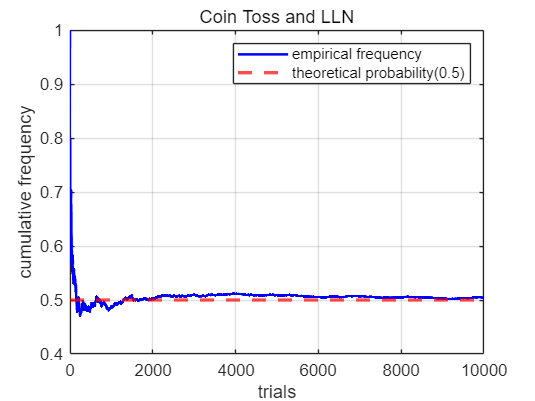

clear; clc; close all;
N = 10000;
tosses = randi([0, 1], 1, N);
cum_heads = cumsum(tosses);
trials = 1:N;
freq = cum_heads ./ trials;
plot(trials, freq, 'b-', 'LineWidth', 1.5);
hold on;
yline(0.5, 'r--', 'LineWidth', 2);
title('Coin Toss and LLN');
xlabel('trials');
ylabel('cumulative frequency');
legend('empirical frequency', 'theoretical probability(0.5)');
grid on;